G2_flt= [G1_tf G2_ef];
G2_flt(4,1) = tf([-0.02705  -9.406e-06],[1 5.816e-05 ]);
G2_flt(4,2) = tf([ -0.02186 +1.425e-05],[1 0.0003949 ]);
G2_flt

G2_flt =
 
  From input "RPM" to output...
                  4.676e-07 s + 1.023e-10
   Pitch rate:  ----------------------------
                s^2 + 0.003052 s + 6.571e-06
 
                 9.563e-08 s - 2.736e-11
   Velocity:  -----------------------------
              s^2 + 1.423e-05 s + 3.829e-07
 
                -2.158e-07 s + 3.738e-11
   Altitude:  -----------------------------
              s^2 + 2.896e-17 s + 3.073e-07
 
       -0.02705 s - 9.406e-06
   4:  ----------------------
           s + 5.816e-05
 
  From input "Elevator deflection" to output...
                   0.06949 s + 1.835e-06
   Pitch rate:  ---------------------------
                s^2 + 0.01136 s + 5.688e-06
 
                 0.03534 s - 9.966e-06
   Velocity:  ----------------------------
              s^2 + 0.001641 s + 1.627e-06
 
                 -0.02214 s + 1.449e-05
   Altitude:  -----------------------------
              s^2 + 0.0004084 s + 2.734e-07
 
       -0.02186 s + 1.425e-05
   4:  -

damp(G2_flt)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.82e-05                 1.00e+00       5.82e-05         1.72e+04    
 -3.95e-04                 1.00e+00       3.95e-04         2.53e+03    
 -2.04e-04 + 4.81e-04i     3.91e-01       5.23e-04         4.90e+03    
 -2.04e-04 - 4.81e-04i     3.91e-01       5.23e-04         4.90e+03    
 -5.25e-04                 1.00e+00       5.25e-04         1.90e+03    
 -1.45e-17 + 5.54e-04i     2.61e-14       5.54e-04         6.91e+16    
 -1.45e-17 - 5.54e-04i     2.61e-14       5.54e-04         6.91e+16    
 -7.11e-06 + 6.19e-04i     1.15e-02       6.19e-04         1.41e+05    
 -7.11e-06 - 6.19e-04i     1.15e-02       6.19e-04         1.41e+05    
 -8.21e-04 + 9.77e-04i     6.43e-01       1.28e-03         1.22e

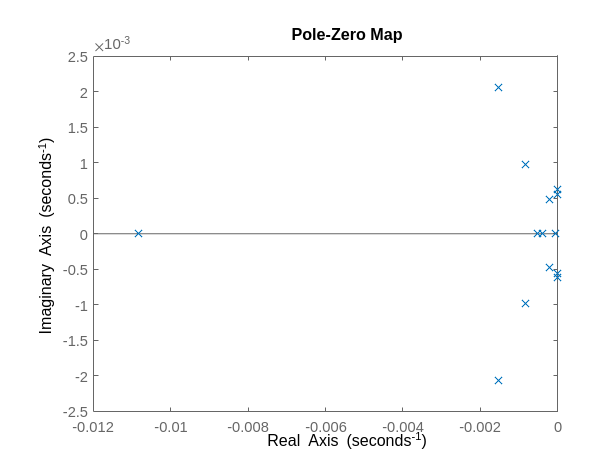

pzmap(G2_flt)

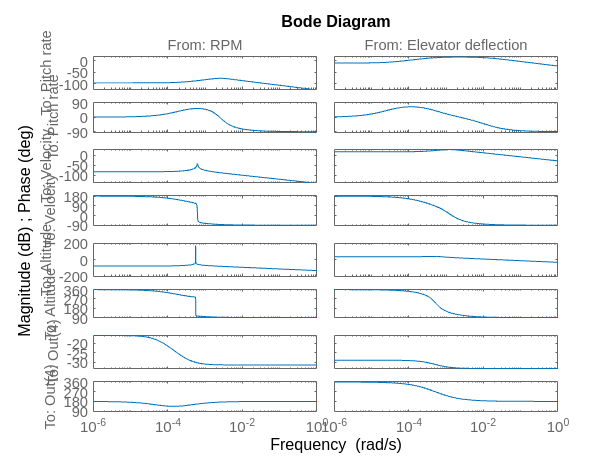

bode(G2_flt);

G3_flt = [G3_tf G3_ef];
G3_flt(4,1) = tf([0.01103 +9.791e-06],[1 0.0002023]);
G3_flt(4,2) = tf([-3.425 +3.307e-05],[1 0.2868]);
G3_flt

G3_flt =
 
  From input "RPM" to output...
                0.0003538 s - 1.86e-06
   Pitch rate:  ----------------------
                s^2 - 41.28 s + 0.2363
 
                -2.078e-08 s + 1.696e-10
   Velocity:  -----------------------------
              s^2 - 0.0001377 s + 2.699e-07
 
                -4.686e-08 s + 1.065e-09
   Altitude:  -----------------------------
              s^2 + 3.991e-05 s + 2.806e-07
 
       0.01103 s + 9.791e-06
   4:  ---------------------
           s + 0.0002023
 
  From input "Elevator deflection" to output...
                   0.07153 s - 3.45e-07
   Pitch rate:  ---------------------------
                s^2 + 0.01092 s + 1.894e-06
 
                  0.02806 s - 2.961e-06
   Velocity:  -----------------------------
              s^2 + 0.0002766 s + 1.438e-06
 
                 -4.759 s + 3.588e-05
   Altitude:  --------------------------
              s^2 + 0.4011 s - 1.176e-05
 
       -3.425 s + 3.307e-05
   4:  --------------------
     

damp(G3_flt)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  2.93e-05                -1.00e+00       2.93e-05        -3.41e+04    
 -1.76e-04                 1.00e+00       1.76e-04         5.67e+03    
 -2.02e-04                 1.00e+00       2.02e-04         4.94e+03    
  6.89e-05 + 5.15e-04i    -1.33e-01       5.20e-04        -1.45e+04    
  6.89e-05 - 5.15e-04i    -1.33e-01       5.20e-04        -1.45e+04    
 -2.00e-05 + 5.29e-04i     3.77e-02       5.30e-04         5.01e+04    
 -2.00e-05 - 5.29e-04i     3.77e-02       5.30e-04         5.01e+04    
 -1.38e-04 + 1.19e-03i     1.15e-01       1.20e-03         7.23e+03    
 -1.38e-04 - 1.19e-03i     1.15e-01       1.20e-03         7.23e+03    
  5.72e-03                -1.00e+00       5.72e-03        -1.75e

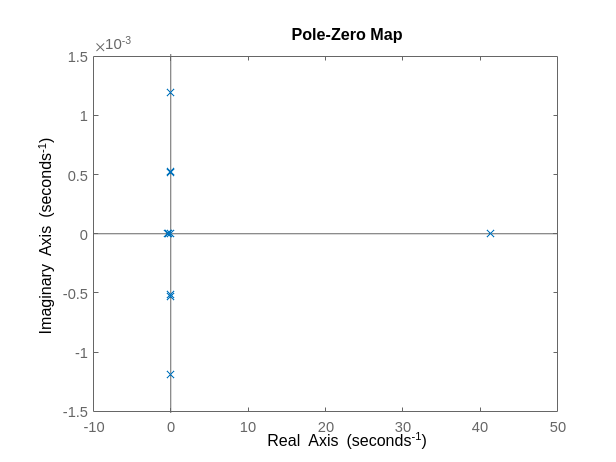

pzmap(G3_flt)

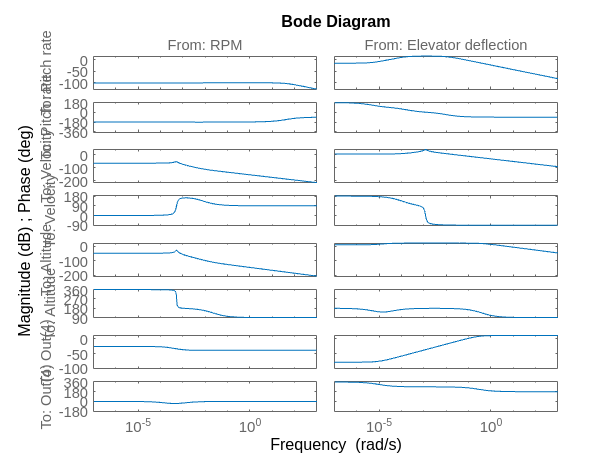

bode(G3_flt)